# **DSP HW3**

**By: 106061151 劉安得**

## **1. (a)**


$$H\left(z\right)=\frac{1}{4}+\frac{1}{4}z^{-1} -\frac{1}{4}z^{-2} -\frac{1}{4}z^{-3}$$


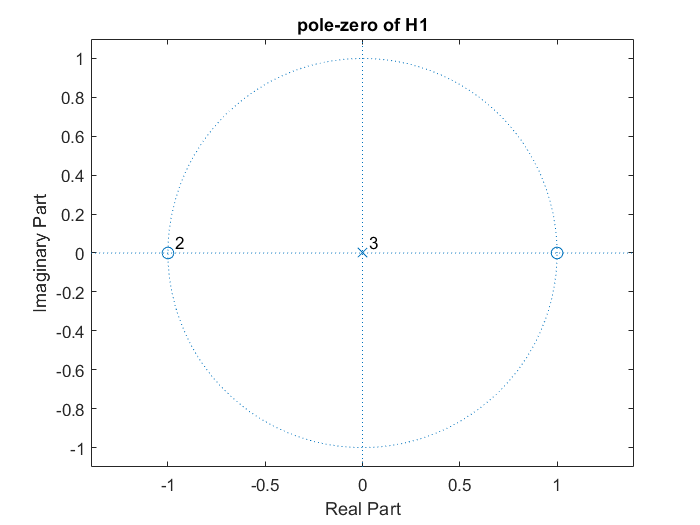

%Prob. 1(a)
w = linspace(-pi, pi, 50);
b1 = [1/4 1/4 -1/4 -1/4];
[h1, w] = freqz(b1, 1, w);

figure
zplane(b1, 1)
title('pole-zero of H1')

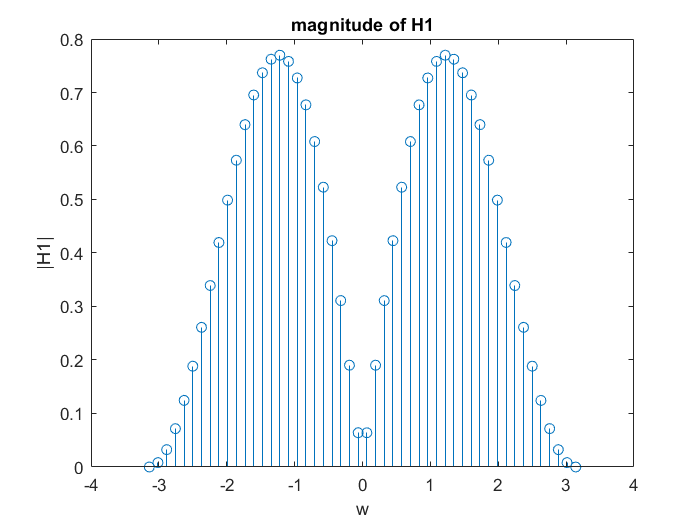


figure
stem(w, abs(h1))
title('magnitude of H1')
xlabel('w')
ylabel('|H1|')

這個系統的 zero 在 1 and -1 ，因此當 w = 0 and +/-pi 時，the magnitude of frequency repoounse 會為 0

## **1. (b)**


$$H\left(z\right)=\frac{\left(1-z^{-4} \right)}{1-0\ldotp 6561z^{-1} }$$


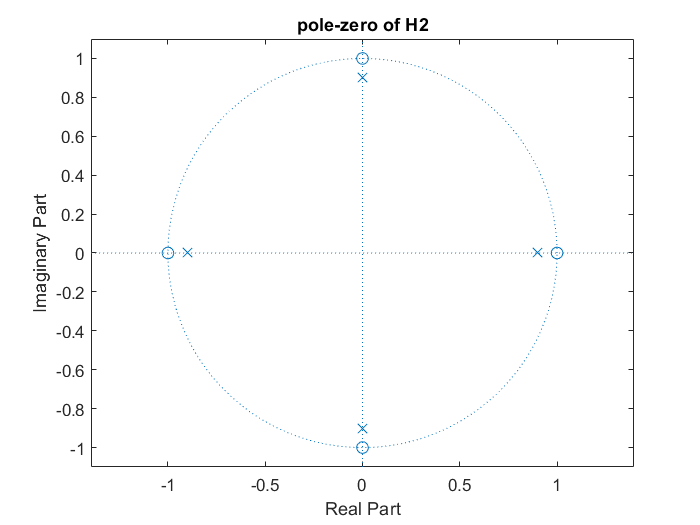

%Prob. 1(b)
b2 = [1 0 0 0 -1];
a2 = [1 0 0 0 -0.6561];
[h2, w2] = freqz(b2, a2, w);

figure
zplane(b2, a2)
title('pole-zero of H2')

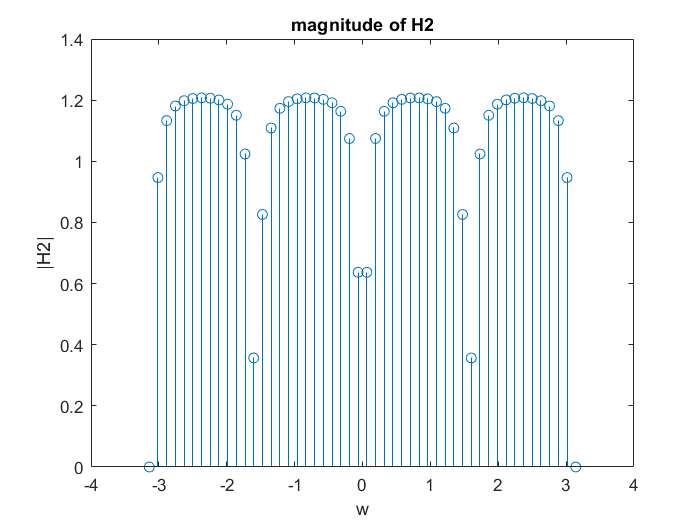


figure
stem(w, abs(h2))
title('magnitude of H2')
xlabel('w')
ylabel('|H2|')

這個系統是一個 norch filter，在 +/-1 and +/-i，因為那四個點上有 zero，the magnitude of frequency repoounse 會為 0。不過一離開那四個點，因為裡面有一個 pole 去抵銷 zero 的效應，因此 magnitude 會迅速變回 1

## 3. (b)

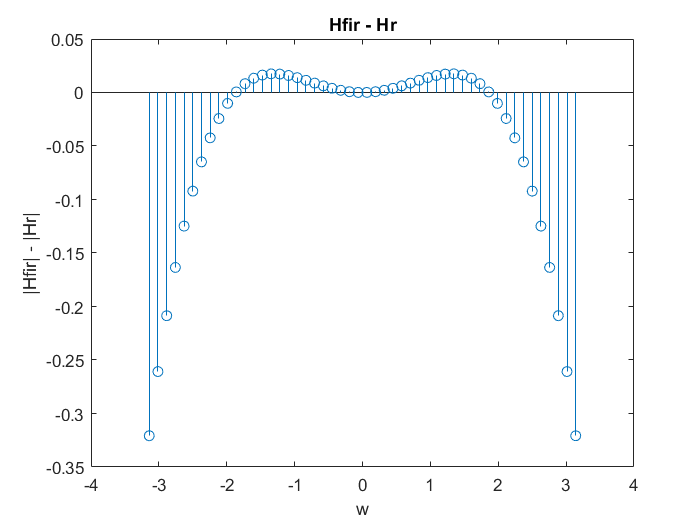

%Prob. 3(b)
w = linspace(-pi, pi, 50);
h1 = w/2./sin(w/2);
b  = [-1/16 9/8 -1/16];
[h2,w] = freqz(b, 1, w);
dh1 = abs(h2)-abs(h1);

figure
stem(w, dh1)
title('Hfir - Hr')
xlabel('w')
ylabel('|Hfir| - |Hr|')

在 |w| < 2，兩者 magnitude 十分接近，不過 |w| > 2 後就越差越多 

## 3. (c)

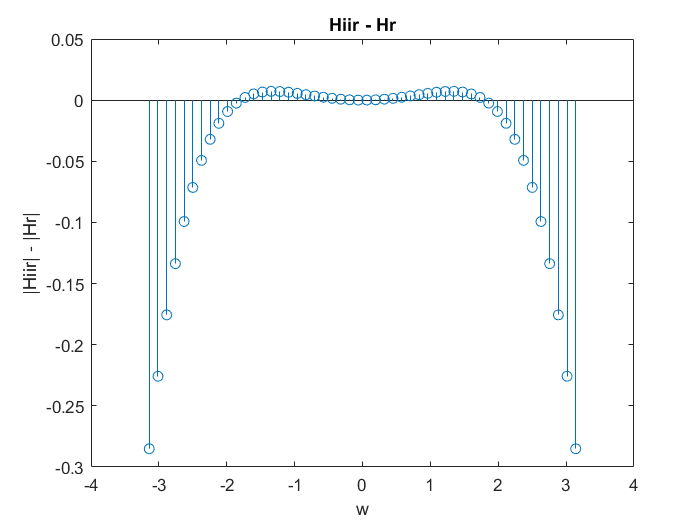

%Prob. 3(c)
a  = [8 1];
[h3,w1] = freqz(9, a, w);
dh2 = abs(h3)-abs(h1);

figure
stem(w, dh2)
title('Hiir - Hr')
xlabel('w')
ylabel('|Hiir| - |Hr|')

與 FIR 相比，IIR 又更接近 ideal filter

## 4. (c)

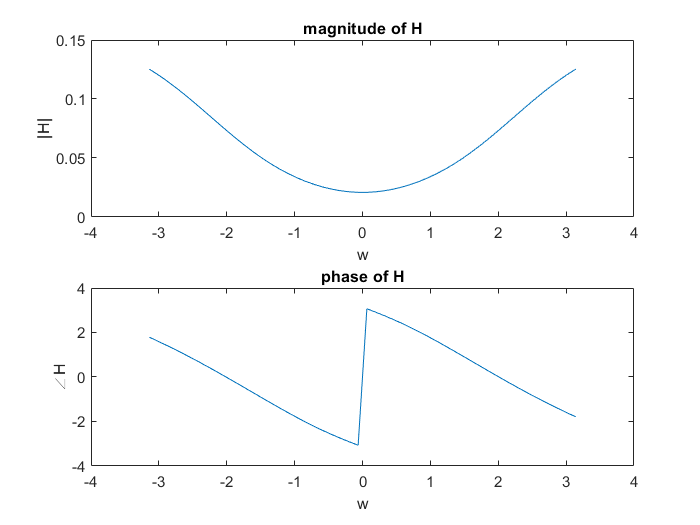

%Prob. 4(c)
w = linspace(-pi, pi, 50);
b1 = [1 -6 10 2 -15];
a1 = [1 15 100 370 744 720];
h1 = freqs(b1, a1, w);

figure
subplot(2, 1, 1)
plot(w, abs(h1))
title('magnitude of H')
xlabel('w')
ylabel('|H|')
subplot(2, 1, 2)
plot(w, angle(h1))
title('phase of H')
xlabel('w')
ylabel('∠H')

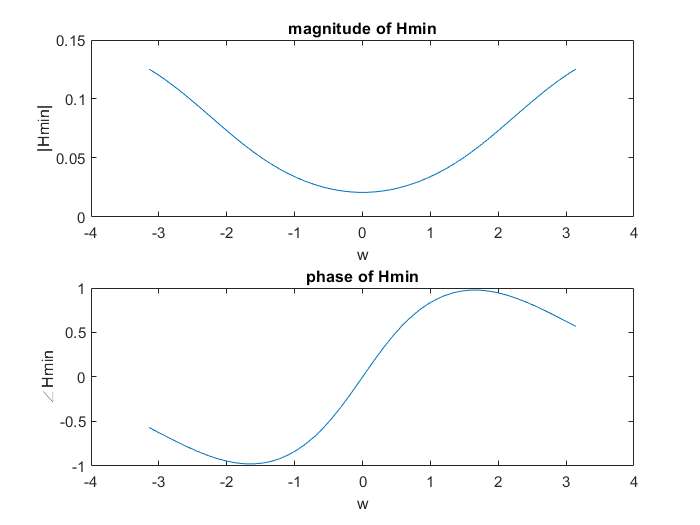


z1 = [-3 -1 -2+i -2-i]';
p1 = [-5 -3+3i -3-3i -2+2i -2-2i]';
k1 = 1;
[b2,a2] = zp2tf(z1, p1, k1);
h2 = freqs(b2, a2, w);

figure
subplot(2, 1, 1)
plot(w, abs(h2))
title('magnitude of Hmin')
xlabel('w')
ylabel('|Hmin|')
subplot(2, 1, 2)
plot(w, angle(h2))
title('phase of Hmin')
xlabel('w')
ylabel('∠Hmin')

Hmin 有較小的 phase lag 和 group delay

它有較圓滑的 phase response

## 4. (d)

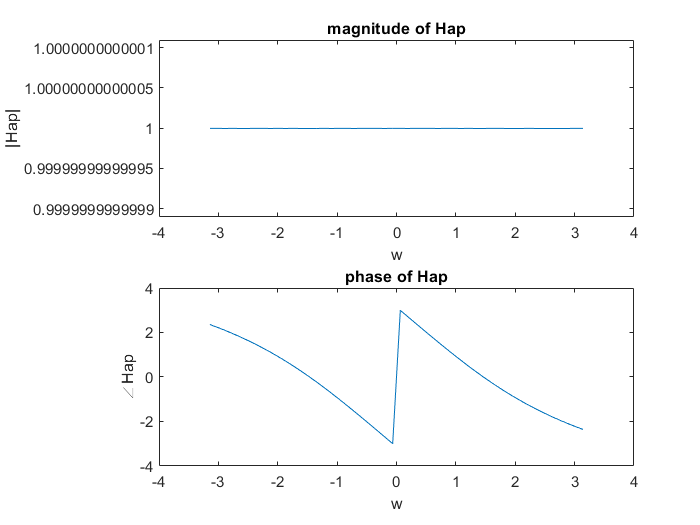

%Prob. 4(d)
z2 = [3 2+i 2-i]';
p2 = [-3 -2+i -2-i];
k2 = 1;
[b3,a3] = zp2tf(z2, p2, k2);
h3 = freqs(b3, a3, w);

figure
subplot(2, 1, 1)
plot(w, abs(h3))
title('magnitude of Hap')
xlabel('w')
ylabel('|Hap|')
subplot(2, 1, 2)
plot(w, angle(h3))
title('phase of Hap')
xlabel('w')
ylabel('∠Hap')

## 5. (b)

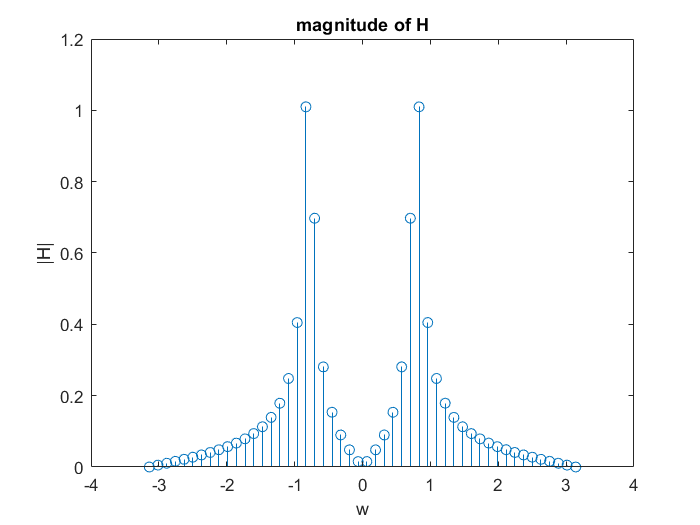

%Prob. 5(b)
w = linspace(-pi, pi, 50);
z = [1 -1]';
p = [0.95*sqrt(2)/2*(1+i) 0.95*sqrt(2)/2*(1-i)]';
k = 0.066;
[b,a] = zp2tf(z, p, k);
h = freqz(b, a, w);

figure
stem(w, abs(h))
title('magnitude of H')
xlabel('w')
ylabel('|H|')

## 5. (c)

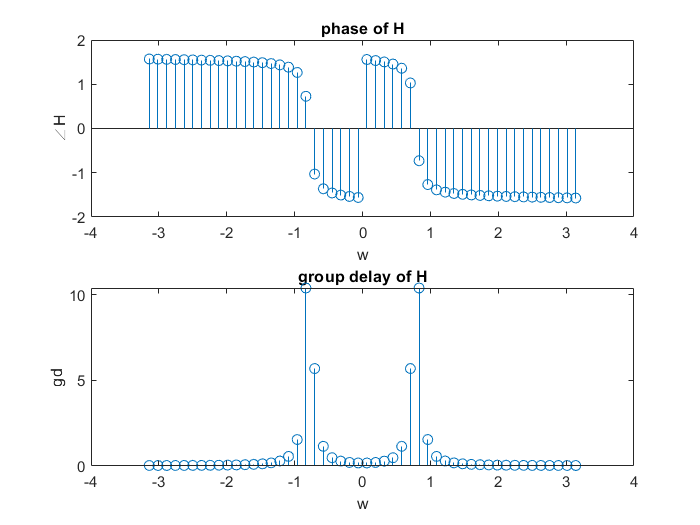

%Prob. 5(c)
gd = grpdelay(b, a, w);

figure
subplot(2, 1, 1)
stem(w, angle(h))
title('phase of H')
xlabel('w')
ylabel('∠H')
subplot(2, 1, 2)
stem(w, gd)
title('group delay of H')
xlabel('w')
ylabel('gd')

## 6. (b)

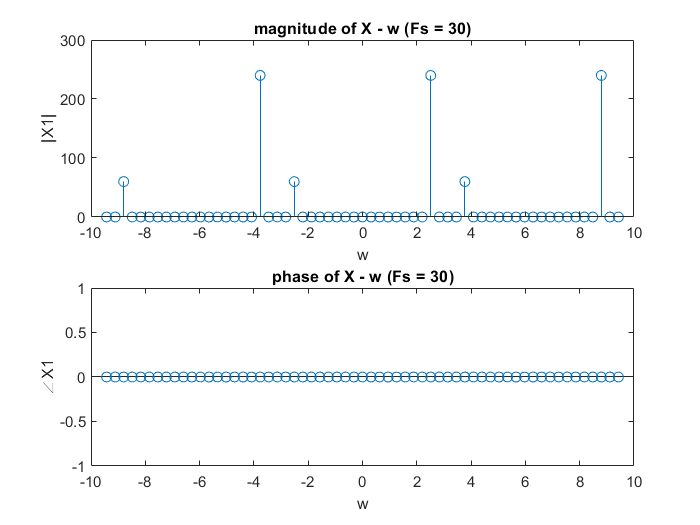

%Prob. 6(b)
w = linspace(-3*pi, 3*pi, 61);
Fs1 = 30;
T1 = 1/Fs1;
F1 = linspace(-3/2/T1, 3/2/T1, 61);
X1 = zeros(1, 61);
for N = 1:61
    W = (N-31)/10*pi;
    for k = -1:1
        if (W-2*pi*k)/T1 - 16*pi == 0
            X1(N)= X1(N) + 1/T1*4;
        elseif (W-2*pi*k)/T1 + 16*pi == 0
            X1(N)= X1(N) + 1/T1*2;
        elseif (W-2*pi*k)/T1 - 24*pi == 0
            X1(N)= X1(N) + 1/T1*8;
        elseif (W-2*pi*k)/T1 + 24*pi == 0
            X1(N)= X1(N) + 1/T1*2;
        end
    end
end

figure
subplot(2, 1, 1)
stem(w, abs(X1))
title('magnitude of X - w (Fs = 30)')
xlabel('w')
ylabel('|X1|')
subplot(2, 1, 2)
stem(w, angle(X1))
title('phase of X - w (Fs = 30)')
xlabel('w')
ylabel('∠X1')

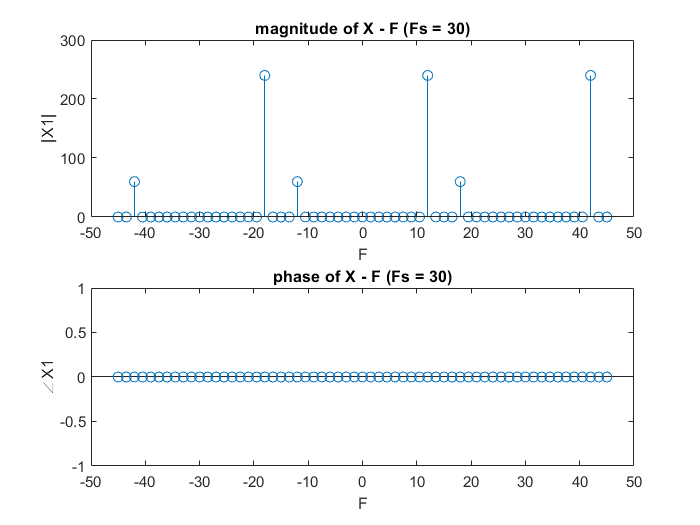

figure
subplot(2, 1, 1)
stem(F1, abs(X1))
title('magnitude of X - F (Fs = 30)')
xlabel('F')
ylabel('|X1|')
subplot(2, 1, 2)
stem(F1, angle(X1))
title('phase of X - F (Fs = 30)')
xlabel('F')
ylabel('∠X1')


$$\Omega_s =2\pi F_s =60\pi >2*24\pi$$


Yes, xc(t) can be recovered from x[n]

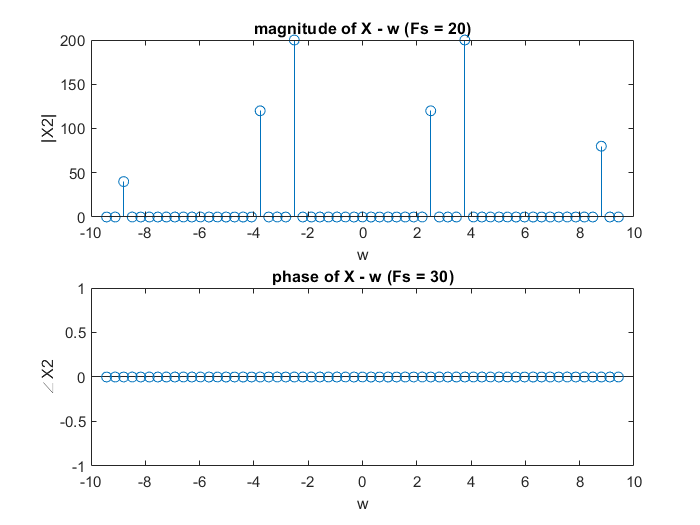

Fs2 = 20;
T2 = 1/Fs2;
F2 = linspace(-3/2/T2, 3/2/T2, 61);
X2 = zeros(1, 61);
for N = 1:61
    W = (N-31)/10*pi;
    for k = -1:1
        if (W-2*pi*k)/T2 - 16*pi == 0
            X2(N)= X2(N) + 1/T2*4;
        elseif (W-2*pi*k)/T2 + 16*pi == 0
            X2(N)= X2(N) + 1/T2*2;
        elseif (W-2*pi*k)/T2 - 24*pi == 0
            X2(N)= X2(N) + 1/T2*8;
        elseif (W-2*pi*k)/T2 + 24*pi == 0
            X2(N)= X2(N) + 1/T2*2;
        end
    end
end

figure
subplot(2, 1, 1)
stem(w, abs(X2))
title('magnitude of X - w (Fs = 20)')
xlabel('w')
ylabel('|X2|')
subplot(2, 1, 2)
stem(w, angle(X2))
title('phase of X - w (Fs = 30)')
xlabel('w')
ylabel('∠X2')

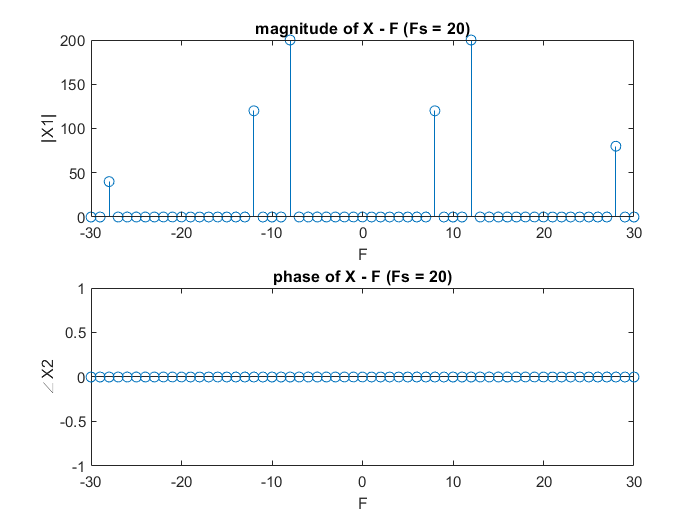


figure
subplot(2, 1, 1)
stem(F2, abs(X2))
title('magnitude of X - F (Fs = 20)')
xlabel('F')
ylabel('|X1|')
subplot(2, 1, 2)
stem(F2, angle(X2))
title('phase of X - F (Fs = 20)')
xlabel('F')
ylabel('∠X2')


$$\Omega_s =2\pi F_s =40\pi >2*24\pi$$


Yes, xc(t) can't be recovered from x[n]

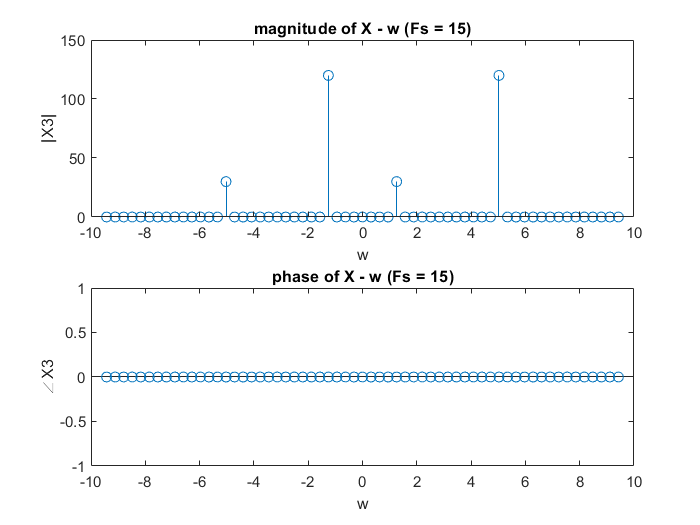

Fs3 = 15;
T3 = 1/Fs3;
F3 = linspace(-3/2/T3, 3/2/T3, 61);
X3 = zeros(1, 61);
for N = 1:61
    W = (N-31)/10*pi;
    for k = -1:1
        if (W-2*pi*k)/T3 - 16*pi == 0
            X3(N)= X3(N) + 1/T3*4;
        elseif (W-2*pi*k)/T3 + 16*pi == 0
            X3(N)= X3(N) + 1/T3*2;
        elseif (W-2*pi*k)/T3 - 24*pi == 0
            X3(N)= X3(N) + 1/T3*8;
        elseif (W-2*pi*k)/T3 + 24*pi == 0
            X3(N)= X3(N) + 1/T3*2;
        end
    end
end

figure
subplot(2, 1, 1)
stem(w, abs(X3))
title('magnitude of X - w (Fs = 15)')
xlabel('w')
ylabel('|X3|')
subplot(2, 1, 2)
stem(w, angle(X3))
title('phase of X - w (Fs = 15)')
xlabel('w')
ylabel('∠X3')

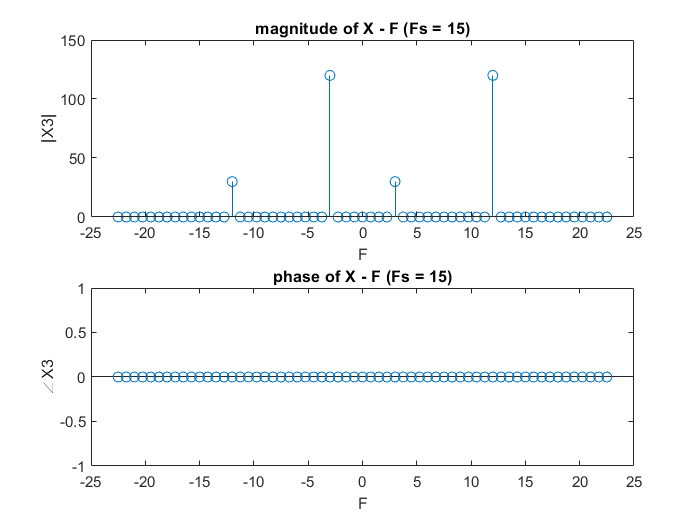


figure
subplot(2, 1, 1)
stem(F3, abs(X3))
title('magnitude of X - F (Fs = 15)')
xlabel('F')
ylabel('|X3|')
subplot(2, 1, 2)
stem(F3, angle(X3))
title('phase of X - F (Fs = 15)')
xlabel('F')
ylabel('∠X3')


$$\Omega_s =2\pi F_s =30\pi >2*24\pi$$


Yes, xc(t) can't be recovered from x[n]

## 8. (a)


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =x\left\lbrack n-15\right\rbrack \\
Y\left(z\right)=z^{-15} X\left(z\right)\\
H\left(z\right)=z^{-15} 
\end{array}$$


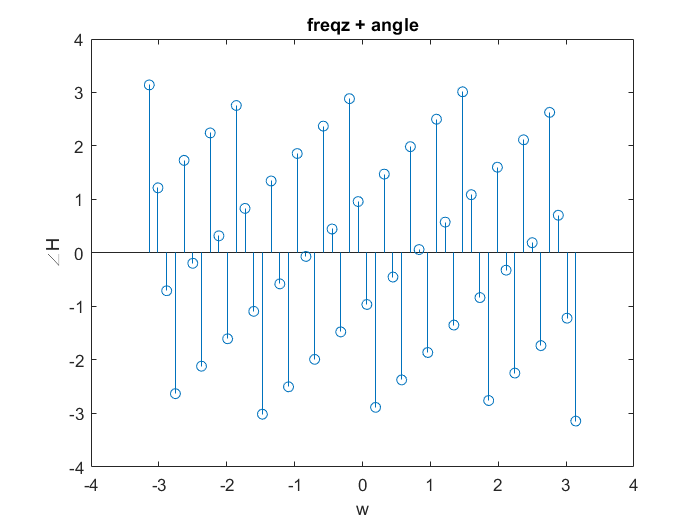

%Prob. 8(a)
w = linspace(-pi, pi, 50);
b1 = [zeros(1, 15), 1];
h1 = freqz(b1, 1, w);
P1 = angle(h1);

figure
stem(w, angle(h1))
title('freqz + angle')
xlabel('w')
ylabel('∠H')

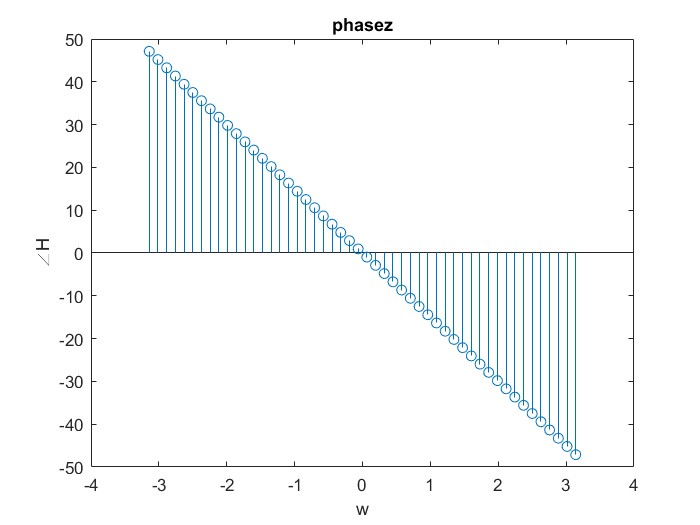


phi1 = phasez(b1, 1, w);
figure
stem(w, phi1)
title('phasez')
xlabel('w')
ylabel('∠H')

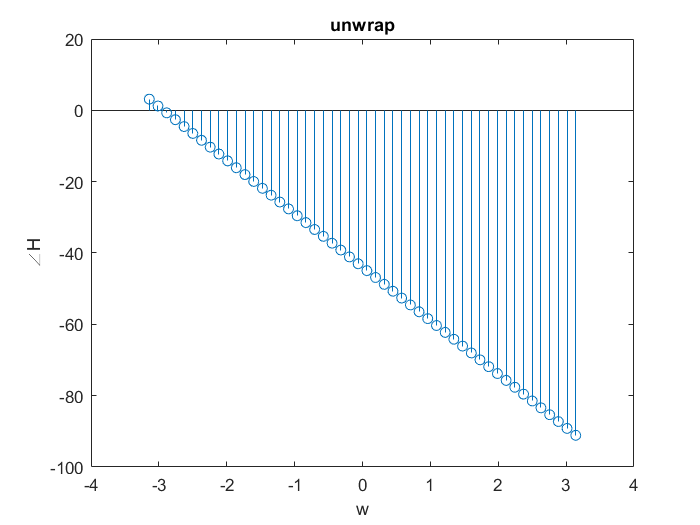


Q1 = unwrap(P1);

figure
stem(w, Q1)
title('unwrap')
xlabel('w')
ylabel('∠H')

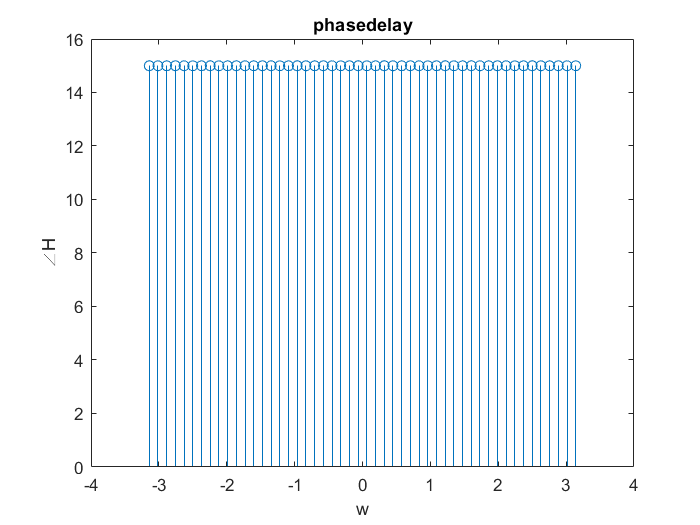


phi2 = phasedelay(b1, 1, w);

figure
stem(w, phi2)
title('phasedelay')
xlabel('w')
ylabel('∠H')

## 8.(b)

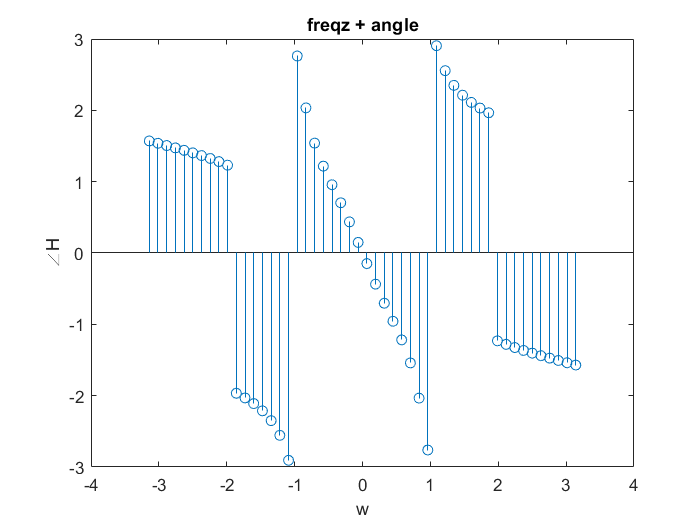

%Prob. 8(b)
b2 = [1 1.655 1.655 1];
a2 = [1 -1.57 1.264  -0.4];
h2 = freqz(b2, a2, w);
P2 = angle(h2);

figure
stem(w, angle(h2))
title('freqz + angle')
xlabel('w')
ylabel('∠H')

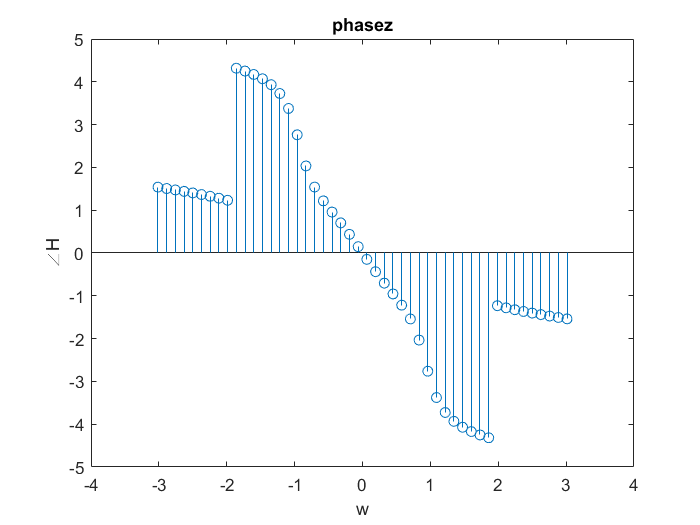


phi3 = phasez(b2, a2, w);
figure
stem(w, phi3)
title('phasez')
xlabel('w')
ylabel('∠H')

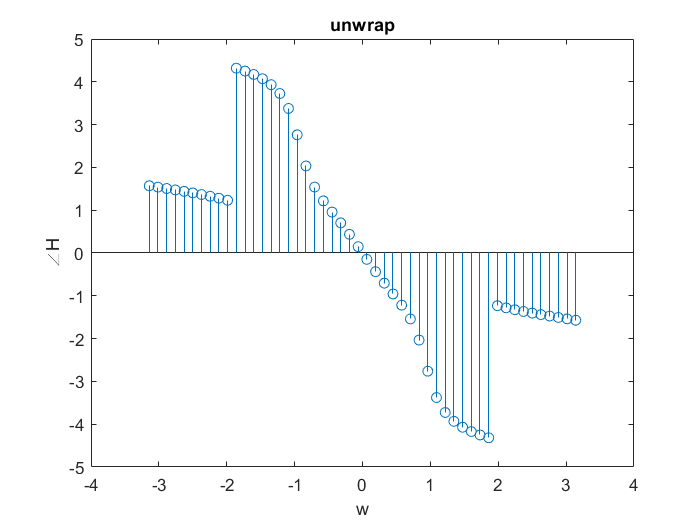


Q2 = unwrap(P2);

figure
stem(w, Q2)
title('unwrap')
xlabel('w')
ylabel('∠H')

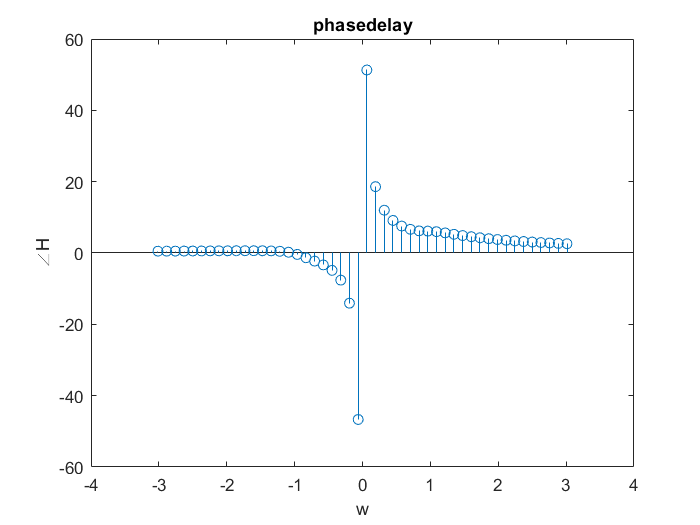


phi4 = phasedelay(b2, a2, w);

figure
stem(w, phi4)
title('phasedelay')
xlabel('w')
ylabel('∠H')

## 9. (a)


$$H\left(z\right)=1-2z^{-1} +3z^{-2} -4z^{-3} +4z^{-5} -3z^{-6} +2z^{-7} -z^{-8}$$


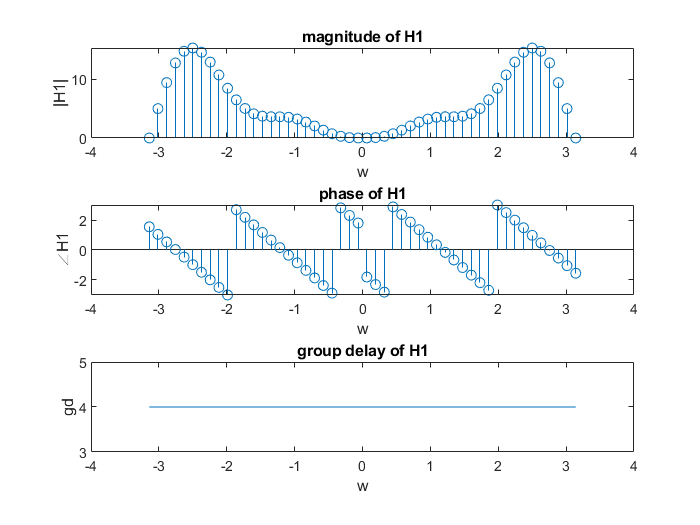

%Prob. 9(a)
w = linspace(-pi, pi, 50);
b1 = [1 -2 3 -4 0 4 -3 2 -1];
h1 = freqz(b1, 1, w);
gd1 = grpdelay(b1, 1, w);

figure
subplot(3, 1, 1)
stem(w, abs(h1))
title('magnitude of H1')
xlabel('w')
ylabel('|H1|')
subplot(3, 1, 2)
stem(w, angle(h1))
title('phase of H1')
xlabel('w')
ylabel('∠H1')
subplot(3, 1, 3)
plot(w, gd1)
title('group delay of H1')
xlabel('w')
ylabel('gd')

## 9. (b)


$$H\left(z\right)=10z^{-10}$$


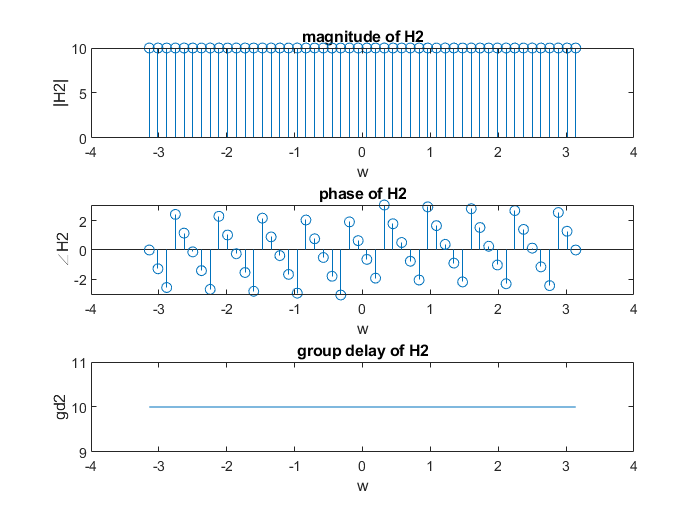

%Prob. 9(b)
b2 = [zeros(1, 10) 10];
h2 = freqz(b2, 1, w);
gd2 = grpdelay(b2, 1, w);

figure
subplot(3, 1, 1)
stem(w, abs(h2))
title('magnitude of H2')
xlabel('w')
ylabel('|H2|')
subplot(3, 1, 2)
stem(w, angle(h2))
title('phase of H2')
xlabel('w')
ylabel('∠H2')
subplot(3, 1, 3)
plot(w, gd2)
title('group delay of H2')
xlabel('w')
ylabel('gd2')

## 10. 

To find maximum-phase, find the pole and zero of minimum-phase, and reciprocal conjugate them. Then the new pole, zero is the pole, zero of maximum-phase

## 10. (a)


$$H\left(z\right)=\frac{\left(z^2 +2z+1\ldotp 75\right)}{z^2 -0\ldotp 5z}=\frac{\left(1+2z^{-1} +1\ldotp 75z^{-2} \right)}{1-0\ldotp 5z^{-1} }$$


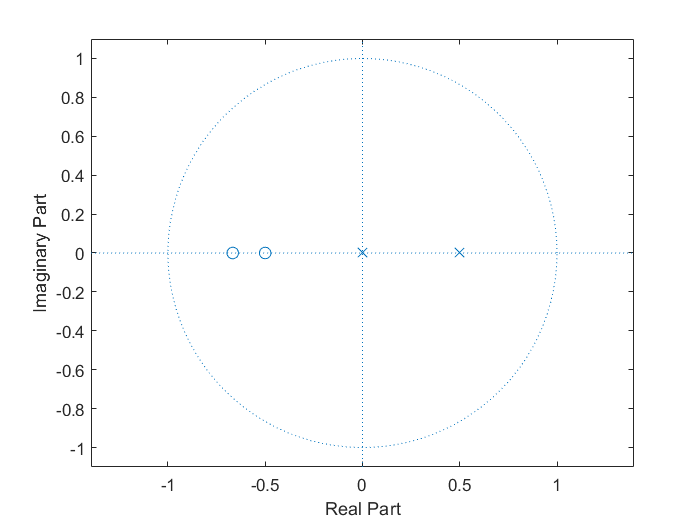

%Prob. 10(a)
b1 = [1 2 0.75];
a1 = [1 -0.5];

b1_min = polystab(b1);
a1_min = polystab(a1);

figure
title('minimum-phase')
zplane(b1_min, a1_min)

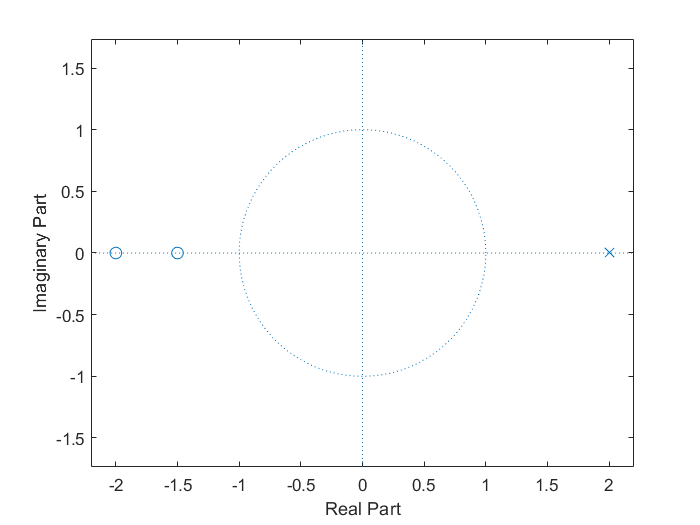


sys1 = tf(b1_min, a1_min);
Z1 = zero(sys1);
P1 = pole(sys1);
Z1_recip = conj(1./Z1);
P1_recip = 1./P1;

figure
title('maximum-phase')
zplane(Z1_recip, P1_recip)

## 10. (b)

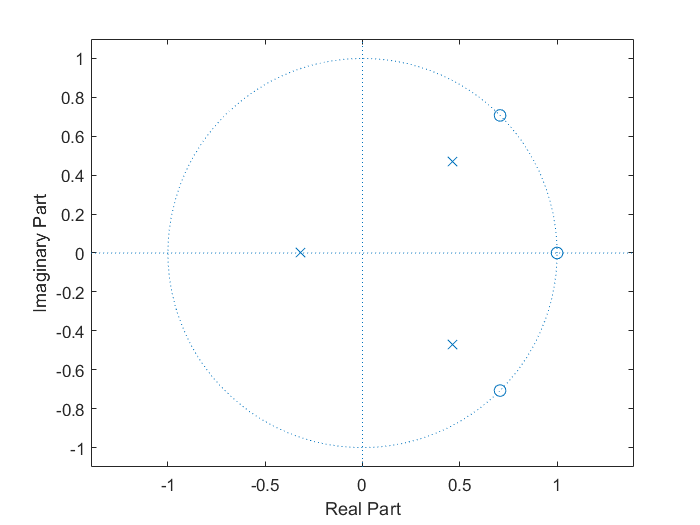

%Prob. 10(b)
b2 = [1 -2.4142 2.4142 -1];
a2 = [1 -1.8 1.62 0.729];

b2_min = polystab(b2);
a2_min = polystab(a2);

figure
title('minimum-phase')
zplane(b2_min, a2_min)

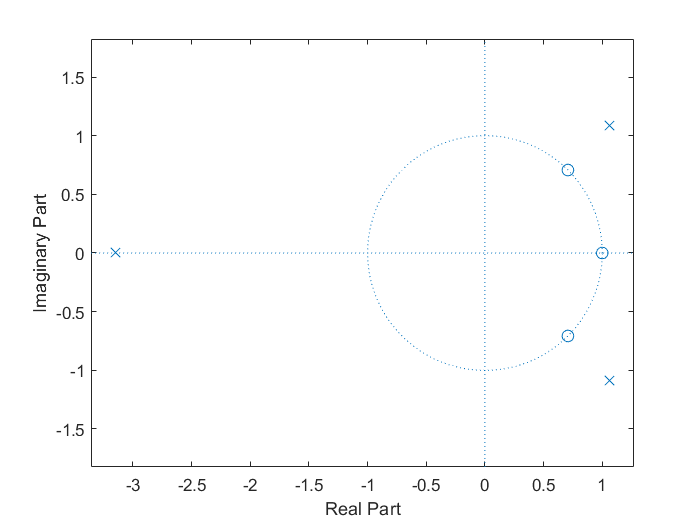


sys2 = tf(b2_min, a2_min);
Z2 = zero(sys2);
P2 = pole(sys2);
Z2_recip = conj(1./Z2);
P2_recip = 1./P2;

figure
title('maximum-phase')
zplane(Z2_recip, P2_recip)

## 11.


$$\begin{array}{l}
x_c \left(t\right)=5\cos \left(200\pi t+\frac{\pi }{6}\right)+4\sin \left(300\pi t\right)=\frac{5}{2}\left(e^{i200\pi t} e^{i\frac{\pi }{6}} +e^{-i200\pi t} e^{-i\frac{\pi }{6}} \right)+2\left(e^{\mathrm{i300}\pi t} -e^{-\mathrm{i300}\pi t} \right)\\
\mathrm{Xc}\left(i\Omega \right)=\frac{5}{2}\left(e^{i\frac{\pi }{6}} \delta \left(\Omega -200\pi \right)+e^{-i\frac{\pi }{6}} \delta \left(\Omega +200\pi \right)\right)+2\left(\delta \left(\Omega -300\pi \right)-\delta \left(\Omega +300\pi \right)\right)\\
X\left(e^{i\omega } \right)=\frac{1}{T}\sum_{k=-\infty }^{\infty } \mathrm{Xc}\left(i\frac{\omega }{T}-i\frac{2\pi }{T}k\right)\\
F=\frac{\omega }{2\pi T}
\end{array}$$


## 11. (a)

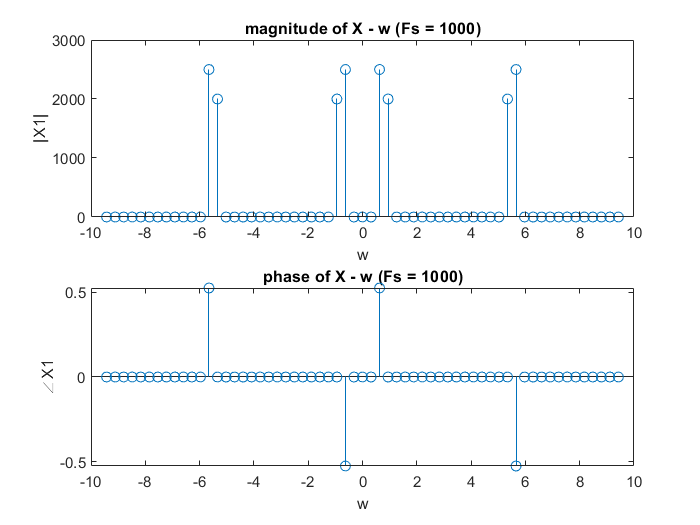

%Prob. 11(a)
w = linspace(-3*pi, 3*pi, 61);
Fs1 = 1000;
T1 = 1/Fs1;
F1 = linspace(-3/2/T1, 3/2/T1, 61);
X1 = zeros(1, 61);
for N = 1:61
    W = (N-31)/10*pi;
    for k = -1:1
        if (W-2*pi*k)/T1 - 200*pi == 0
            X1(N)= X1(N) + 1/T1*5/2*(sqrt(3)/2 + i*1/2);
        elseif (W-2*pi*k)/T1 + 200*pi == 0
            X1(N)= X1(N) + 1/T1*5/2*(sqrt(3)/2 - i*1/2);
        elseif (W-2*pi*k)/T1 - 300*pi == 0
            X1(N)= X1(N) + 1/T1*2;
        elseif (W-2*pi*k)/T1 + 300*pi == 0
            X1(N)= X1(N) + 1/T1*2;
        end
    end
end

figure
subplot(2, 1, 1)
stem(w, abs(X1))
title('magnitude of X - w (Fs = 1000)')
xlabel('w')
ylabel('|X1|')
subplot(2, 1, 2)
stem(w, angle(X1))
title('phase of X - w (Fs = 1000)')
xlabel('w')
ylabel('∠X1')

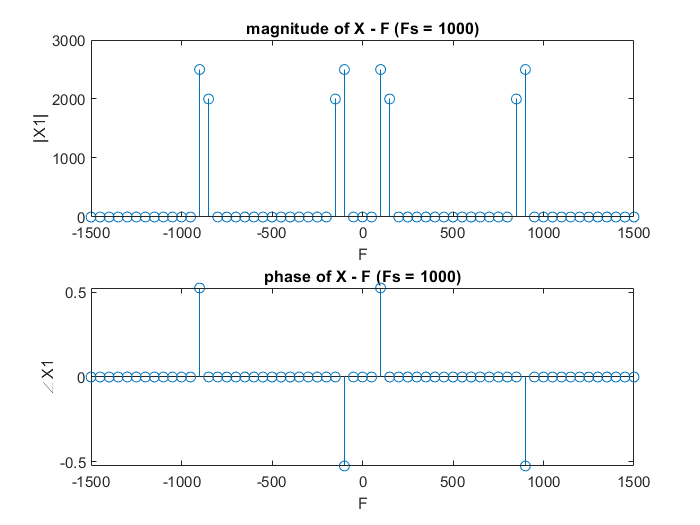


figure
subplot(2, 1, 1)
stem(F1, abs(X1))
title('magnitude of X - F (Fs = 1000)')
xlabel('F')
ylabel('|X1|')
subplot(2, 1, 2)
stem(F1, angle(X1))
title('phase of X - F (Fs = 1000)')
xlabel('F')
ylabel('∠X1')


$$\Omega_s =2\pi F_s =2000\pi >2*300\pi$$


xc(t) can be recovered from x[n]

## 11. (b)

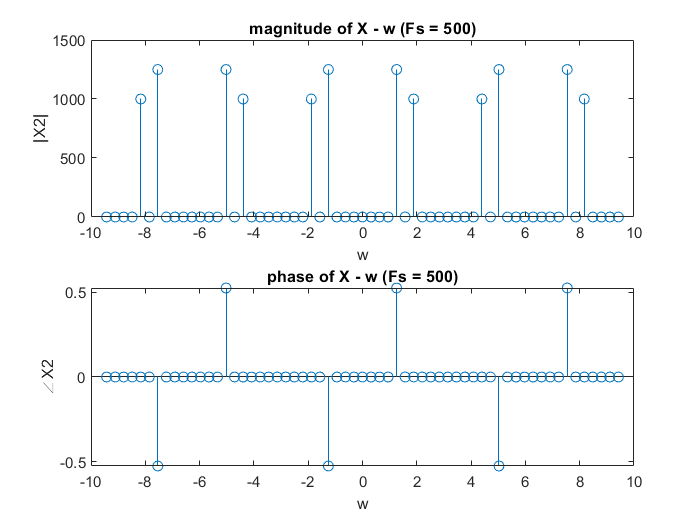

%Prob. 11(b)
Fs2 = 500;
T2 = 1/Fs2;
F2 = linspace(-3/2/T2, 3/2/T2, 61);
X2 = zeros(1, 61);
for N = 1:61
    W = (N-31)/10*pi;
    for k = -1:1
        if (W-2*pi*k)/T2 - 200*pi == 0
            X2(N)= X2(N) + 1/T2*5/2*(sqrt(3)/2 + i*1/2);
        elseif (W-2*pi*k)/T2 + 200*pi == 0
            X2(N)= X2(N) + 1/T2*5/2*(sqrt(3)/2 - i*1/2);
        elseif (W-2*pi*k)/T2 - 300*pi == 0
            X2(N)= X2(N) + 1/T2*2;
        elseif (W-2*pi*k)/T2 + 300*pi == 0
            X2(N)= X2(N) + 1/T2*2;
        end
    end
end

figure
subplot(2, 1, 1)
stem(w, abs(X2))
title('magnitude of X - w (Fs = 500)')
xlabel('w')
ylabel('|X2|')
subplot(2, 1, 2)
stem(w, angle(X2))
title('phase of X - w (Fs = 500)')
xlabel('w')
ylabel('∠X2')

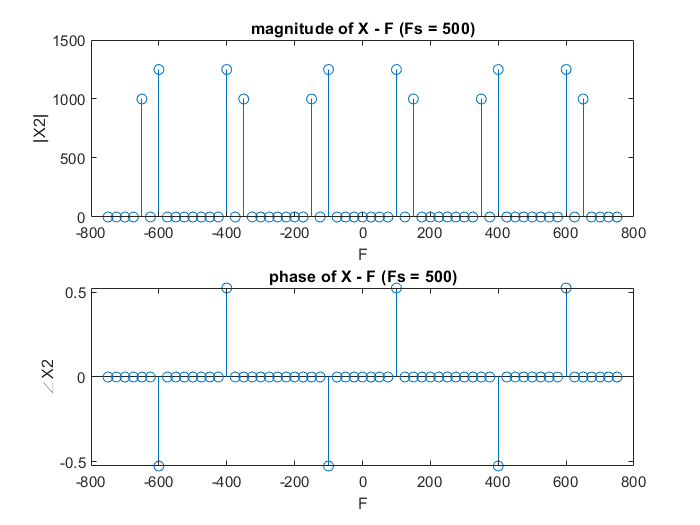


figure
subplot(2, 1, 1)
stem(F2, abs(X2))
title('magnitude of X - F (Fs = 500)')
xlabel('F')
ylabel('|X2|')
subplot(2, 1, 2)
stem(F2, angle(X2))
title('phase of X - F (Fs = 500)')
xlabel('F')
ylabel('∠X2')


$$\Omega_s =2\pi F_s =1000\pi >2*300\pi$$


xc(t) can be recovered from x[n]

## 11. (c)

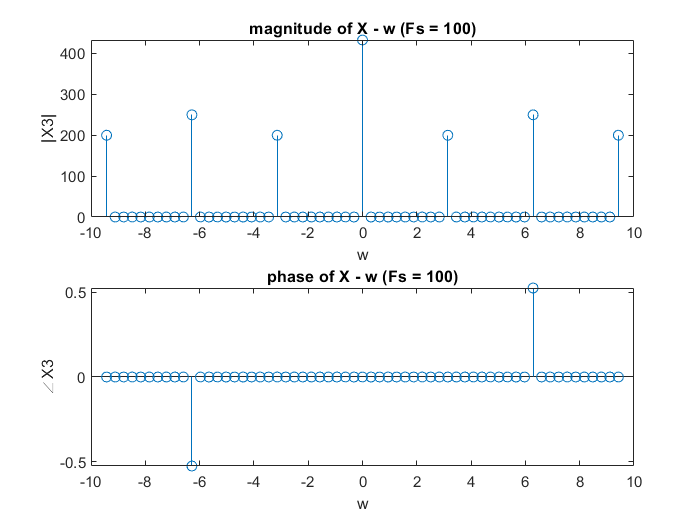

%Prob. 11(c)
Fs3 = 100;
T3 = 1/Fs3;
F3 = linspace(-3/2/T3, 3/2/T3, 61);
X3 = zeros(1, 61);
for N = 1:61
    W = (N-31)/10*pi;
    for k = -1:1
        if (W-2*pi*k)/T3 - 200*pi == 0
            X3(N)= X3(N) + 1/T3*5/2*(sqrt(3)/2 + i*1/2);
        elseif (W-2*pi*k)/T3 + 200*pi == 0
            X3(N)= X3(N) + 1/T3*5/2*(sqrt(3)/2 - i*1/2);
        elseif (W-2*pi*k)/T3 - 300*pi == 0
            X3(N)= X3(N) + 1/T3*2;
        elseif (W-2*pi*k)/T3 + 300*pi == 0
            X3(N)= X3(N) + 1/T3*2;
        end
    end
end

figure
subplot(2, 1, 1)
stem(w, abs(X3))
title('magnitude of X - w (Fs = 100)')
xlabel('w')
ylabel('|X3|')
subplot(2, 1, 2)
stem(w, angle(X3))
title('phase of X - w (Fs = 100)')
xlabel('w')
ylabel('∠X3')

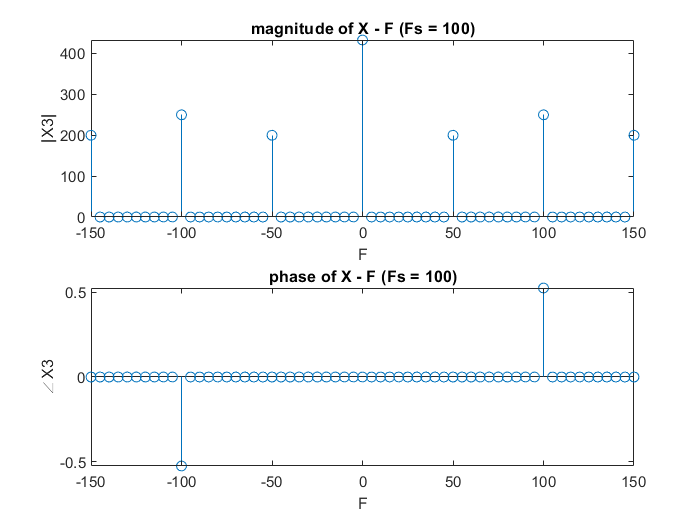


figure
subplot(2, 1, 1)
stem(F3, abs(X3))
title('magnitude of X - F (Fs = 100)')
xlabel('F')
ylabel('|X3|')
subplot(2, 1, 2)
stem(F3, angle(X3))
title('phase of X - F (Fs = 100)')
xlabel('F')
ylabel('∠X3')


$$\Omega_s =2\pi F_s =200\pi >2*300\pi$$


xc(t) can't be recovered from x[n]

## 11. (d)

the nyquist rate is 2*300pi, therefore only if the sampling rate great than 300Hz, xc(t) can be recovered from x[n]